# Modulation Classification - Trained Network

Modulation identification is an important function for an intelligent receiver. It has numerous applications in cognitive radar, software-defined radio, and efficient spectrum management. 

In this exercise, you will explore a pretrained deep learning network and see how it classifies 6 different modulations. 

*Copyright 2024 The MathWorks, Inc.*

## Are You in the Correct Directory?

% Run this to check proper configuration 

% Start from a clean workspace
clearvars

if isfolder('1-HelperFiles')
    disp('You are in the correct directory. Please continue.')
    addpath('1-HelperFiles')
   
else  
    error('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## Load Pre-trained CNN

load modPredNetwork.mat

## Inspect the Network

% Inspect network's layers
net.Layers

ans =   8×1 Layer array with layers:

     1   'sequenceinput'     Sequence Input           Sequence input with 1 dimensions
     2   'conv1d_1'          1-D Convolution          16 8×2 convolutions with stride 1 and padding [0  0]
     3   'relu_1'            ReLU                     ReLU
     4   'conv1d_2'          1-D Convolution          16 8×16 convolutions with stride 1 and padding [0  0]
     5   'relu_2'            ReLU                     ReLU
     6   'globalmaxpool1d'   1-D Global Max Pooling   1-D global max pooling
     7   'fc'                Fully Connected          6 fully connected layer
     8   'softmax'           Softmax                  softmax

% Understand the different classes in the network
classes

classes = 6×1 categorical array
     16QAM 
     64QAM 
     BPSK 
     GFSK 
     PAM4 
     QPSK 

## Classify Modulations 

The trained network takes in frames impaired with Rician multipath fading, center frequency offset,  sampling time drift, and AWGN and predicts the modulation type. 

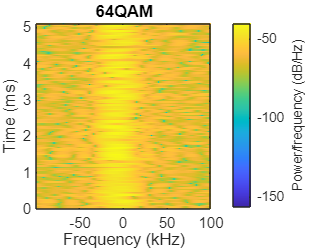

% Select a modulation type 
modType = "64QAM"; 

% Select a random frame of the modulation type and plot its spectrogram 
modFrame = hSelectTestFrame(rxFrames,rxLabels,modType);

% To Do: Feed the frame into the network for classification
% Hint: Specify the name of the network and the data frame above.

scores = predict(net, modFrame); % ADD CODE HERE

% Display output
[predModLabel, predScore] = scores2label(scores, classes);
disp("Predicted class is " + string(predModLabel) + " with score " + predScore + ".")

Predicted class is 16QAM with score 0.48495.


## Observation

Is the network accurate all the time? Are there any modulation types that are being confused by  the network? 

Answers in Exercise 2! 